omega = @(omega1) -0.12*omega1^2 + 7.2e-5*omega1^4 + 8.08;
result = zeros(1, 11);  
for i = 0:10
    result(i+1) = omega(i); 
end

disp(result);

    8.0800    7.9601    7.6012    7.0058    6.1784    5.1250    3.8533    2.3729    0.6949   -1.1676   -3.2000





omega2 = @(w) -1.44e-4*w^3+8.2*w;
result1 = zeros(0,10);
for i1 = 0:10
  result1(i1+1) = omega2(i1);
end

disp(result1);

         0    8.1999   16.3988   24.5961   32.7908   40.9820   49.1689   57.3506   65.5263   73.6950   81.8560



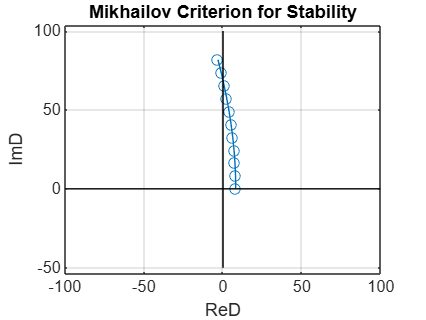


figure;
plot(result, result1, '-o');  


hold on;
line([-100 100], [0 0], 'Color', 'k'); 
line([0 0], [-50 100], 'Color', 'k');  
hold off;

xlabel('ReD');
ylabel('ImD');
title('Mikhailov Criterion for Stability');
grid on;  
axis([-100 100 -50 100]);  
axis equal;  






% disp(result);


% omega2 = @(w) -1.44e-4*w^3+8.2*w;
% for i1 = 0:10
%   disp(result1);
%    result1 = omega2(i1);
%    i1 = i1 + 1;
% end



omega2 = @(w) -1.44e-4*w^3+8.2*w;
result1 = zeros(0:11);
for i1 = 0:11
  result1(i1+1) = omega2(i1);
end

Attempt to grow array along ambiguous dimension.


disp(result1);

figure;
plot(result1, 0:11, '-o');
xlabel('ReD');
ylabel('ImD');
title('Mikhailov criterion');
grid on;



